## Lab #3: Asking a statistical question

## Problem 1

In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.

To make this a bit concrete, we will simulate a little data. Start by simulating 100k 'good' data points assuming Gaussian fluctations.

In order simulating 100k 'good' data points assuming Gaussian fluctations we need mean and stander deviation. In this case the mean will be 12 since the temperature data is mostly consistent with 12 Kelvin and the stander deviation will be 0.4 since the thermometry is 0.4 degree precision.

clear;clc;clf;

mu = 12;
sig = 0.4;

gauss = makedist("Normal", "mu", mu, "sigma", sig);
gooddata = random(gauss,1,100000);

adding the following 'bad' datapoints: {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7} to the good data.

baddata = [10. 10.3 2.1 0. 0. 15.6 22.3 12.7];
temps = [gooddata,baddata];
temps= sort(temps);

As show on the graph the data randomly generated is well fit under the Gaussian distribution curve with mean as 12 and stander deviation as 0.4.

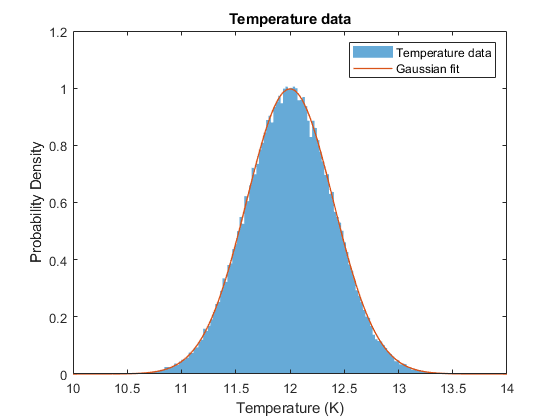


figure (1)
histogram(temps,1000,"Normalization","pdf",'EdgeColor',"none")
hold on
x2 = 10:0.01:14;
plot(x2,pdf(gauss,x2),"LineWidth",1);
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('Probability Density')
title('Temperature data');
xlim([10 14])
hold off

The  statistical question

Since the main point for this part is to define the outliers in over all data. We will keep the data that is 5 sigma within form the mean. Can we find the outliers that exceed this 5 sigma of values?  And is there as better value  for X time sigma that keeps most of  good data and removes most of bad data?

We start with finding the outliers that is 5 sigma away form the mean. Since standered dviation is the same as the sigma for Normal distribution. In order to find threshold of 5 sigma all we need is five times sigma. In this case we find some of the outliers.  

threshold = 5 * sig;
outliers = [temps(temps < (mu - threshold)) temps(temps > (mu + threshold))];
disp(outliers);

         0         0    2.1000   15.6000   22.3000



disp("the number of outliers that exceed 5 sigma is " + length(outliers));

the number of outliers that exceed 5 sigma is 5


Next we try to find optimal value for X time sigma that keeps most of good data and removes most of bad data. One we I think we can do is try as much value as possible for X and find the maxment value of good data identified as being good and maxment value of bad data identified as being bad , and the miniment value of bad data identified as good and the miniment value of good data identified as bad. 

So what I did is create a hunge array of value of prefix for sigma. Then test each prefix to find it's True Pos(good data), True Neg(omission), False Neg(bad data), and False Pos(commission). Find the mininment number of the False Neg and  False Pos occur, and maximent number of the True Pos and True Neg occur. Use the value we found to find the index of the prefix for sigma in the huge array. Pick out the prefix for sigma and find the outliers. Compare the outlier with the good data and bad data to find True Pos(good data), True Neg(omission), False Neg(bad data), and False Pos(commission). 

Since the method I used to find the best prefix for the sigma depend on the random number that I generated. The threshold I chose changes every time I run the lab. So the number of omissions is not a predictable quantity. (some time it show up as 1 or 2 ,but most time is 0)

There are mistakes of commission. They are not avoidable since some of the bad data was close to the range of plus or minus of 0.4 stander diviation. And the method I used is try keeps most of good data and removes most of bad data. Which means if the False Pos go to zero the  Ture Neg woold hugely go up. 

num_true_pos = [];
num_true_neg = [];
num_false_pos = [];
num_false_neg = [];

prefix = linspace(0, 10, 500);
for i = prefix
    
    outliers = [temps(temps < (mu - i * sig )) temps(temps > (mu + i * sig))];
    data_keeped = temps(~ismember(gooddata, outliers));
    
    true_pos = temps(ismember(data_keeped,gooddata));
    true_neg = temps(ismember(outliers, baddata));
    false_pos = temps(ismember(data_keeped, baddata));
    false_neg = temps(ismember(outliers, gooddata));
    
    num_true_pos = [num_true_pos, length(true_pos)];
    num_true_neg = [num_true_neg, length(true_neg)];
    num_false_pos = [num_false_pos, length(false_pos)];
    num_false_neg = [num_false_neg, length(false_neg)];
    
end

[~, index] = min(num_false_neg + num_false_pos);
best_prefix = prefix(index);
[~, index] = max(num_true_pos + num_true_neg);
best_prefix = prefix(index);
outliers = [temps(temps < (mu - best_prefix* sig)) temps(temps > (mu + best_prefix* sig))];
disp("the best prefix for sigma is " + best_prefix);

the best prefix for sigma is 4.7896


disp("number of outliers is " + length(outliers));

number of outliers is 6


disp(["outliers are"  string(outliers)]);

    "outliers are"    "0"    "0"    "2.1"    "10"    "15.6"    "22.3"



TP = length(temps(~ismember(gooddata, outliers))); %True Pos(good data)
FN = length(temps(ismember(baddata, outliers))); %False Neg(bad data)
TN = length(temps(ismember(gooddata, outliers))); %True Neg(omission)
FP = length(temps(~ismember(baddata, outliers))); %False Pos(commission)
disp(["True Pos " + TP , "False Neg " + FN, "False Pos " + FP, "True Neg " + TN]);

    "True Pos 100000"    "False Neg 6"    "False Pos 2"    "True Neg 0"



## Problem 2

In this example we will be looking for asteroids. If we look at the alignment of stars on subsequent images, they don't perfectly align due to atmospheric and instrumental effects (even ignoring proper motion). The resulting distribution is two dimensional, and for this lab let's assume it is a 2D Gaussian with 1 arcsecond RMS. Or said another way, if I histogram how far all the (stationary) stars appear to have moved I get something like: (code unavailable for matlab)

If I have a potential asteroid, it will have some true movement between the images. We would like a '5 sigma' detection of movement. What is that distance in arcseconds?

We want ot know the distance an object has to travel before we can consider it is an asteroid. Inorder to know the distance we would like to ask:

 What is the distance away from the origin might produce a significance position measurement in the 2D Gaussian with 1 arcsecond RMS? In this case the significance position measurement we want is 5 sigma away, and we want know what is the minimum threshold to have 5 sigma detected?